# DeepInterpolation - Tiny Ophys Inference Detailed Example

This example imports and uses a pre-trained DeepInterpolation model in MATLAB for inferring tiny ophys sample data. Includes code details for importing TensorFlow trained networks and formatting imaging data to be run through the deep network.

## Run setup for initialization of path

base_folder = deepinterp.setup();

## Import the Model

The pre-trained network is available on an external file storage, as it is a bit larger (120 MB) than the other example networks. It is automatically downloaded here.

ZipFile=deepinterp.internal.getPretrainedModelFilename('TP-Ai93-450');
[filePathZipFile,filename,ext] = fileparts(ZipFile);
unzip(ZipFile,filePathZipFile);
importednet = importNetworkFromTensorFlow(fullfile(filePathZipFile,filename), Namespace='trainedModel');

Importing the saved model...
Translating the model, this may take a few minutes...
Finished translation. Assembling network...
Import finished.


## Analyze Network

Optionally analyze the network

if false
    analyzeNetwork(importednet)
end

## Import Sample TIFF Volume

ophys = single(tiffreadVolume('ophys_tiny_761605196.tif'));

## **Choose the number of frames to be omitted before and after the predicted frame**

pre_post_omission = ceil(0); 

## **Choose which frame to predict**

target_frame = ceil(60); 

## Pre-processing before DeepInterpolation

The network expects an input of size:

inputSize = importednet.Layers(1).InputSize

inputSize =    512   512    60


The size of the *ophys* image is:

size(ophys)

ans =    512   512   100


Make prediction with the equivalent sized input:

pre_frame = 30; % Fixed number of frames before the predicted frame
post_frame = 30; % Fixed number of frames after the predicted frame

### Drop the omitted frames before prediction

input_index = (target_frame - pre_frame - pre_post_omission) : (target_frame + post_frame + pre_post_omission );
  
pre_post_omission_index = target_frame-pre_post_omission : target_frame+pre_post_omission; % index of frames to be dropped

for drop_frame = pre_post_omission_index
    input_index = input_index(input_index ~= drop_frame); % drop the predicted frame and the frames omitted before and after the predicted frame
end

## Inspect noise level of raw data

By viewing a few frames we can get a sense of the noise level of the raw data

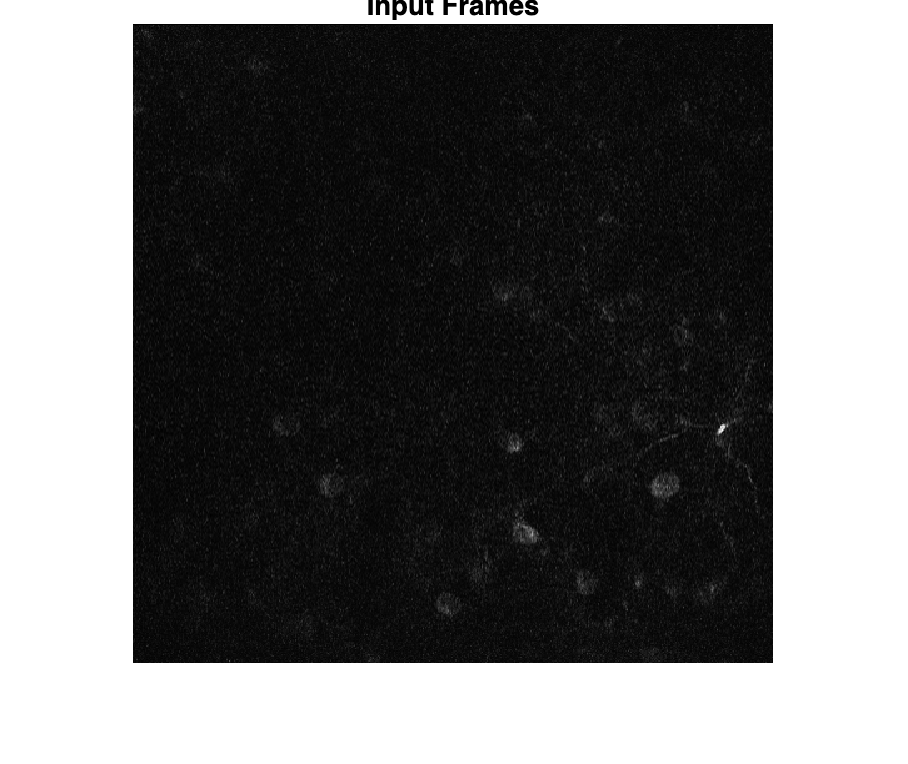

for idx = input_index
    imshow(ophys(:,:,idx), [])
    pause(0.5)
end
title("Input Frames")

### Normalization of frames

[ophys, C, S] = normalize(ophys,3,"center","mean","scale","std"); % where C = mean, S = std

## **Perform DeepInterpolation**

ophysinterp = zeros(size(ophys));
offsets = -pre_frame:post_frame-1;

try
    for t = pre_frame+1 : size(ophys,3) - post_frame
	    ophysinterp(:,:,t) = predict(importednet,ophys(:,:,offsets+t));
    end
catch
    warning('Problem using predict.  Returning null.');
    ophysinterp = [];
end

## Rescale normalized frames

ophys  = (ophys .* S) + C;
ophysinterp = (ophysinterp .* S) + C;

## Plot DeepInterpolation Result

We will now view the result of denoising our raw data using DeepInterpolation

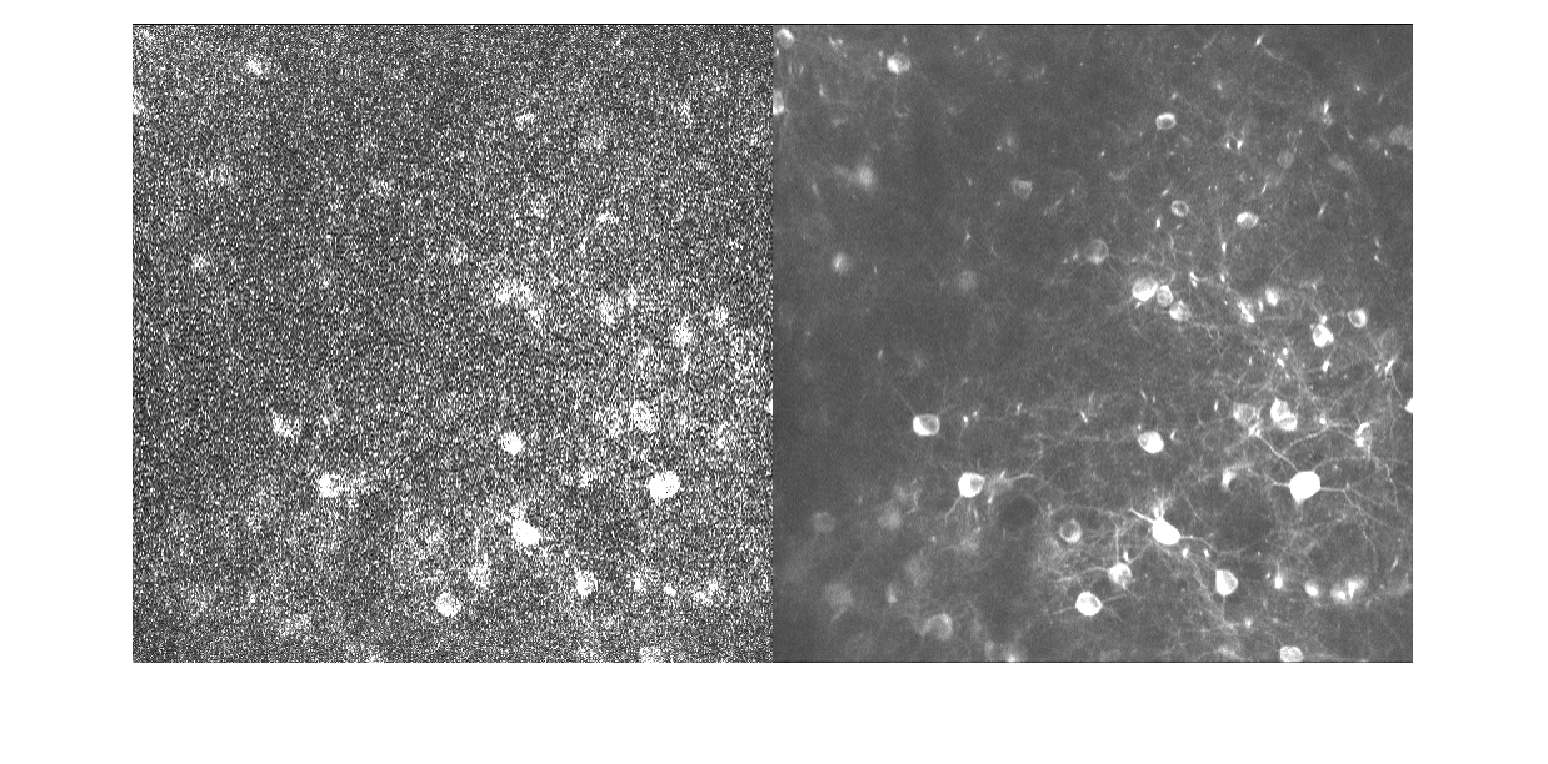

for idx = 31:size(ophys,3)-30
    imshow([ophys(:,:,idx) ophysinterp(:,:,idx)],...
        [0 prctile(ophys(:),95)]);  % scaling image to 0 .. 95 percentile to show range
    pause(0.1);
end